% Full scheduling for two-tone measurements avoiding DP and SNR-bin overlap
clearvars; close all; clc;

% ---------- Parameters ----------
fs = 44100;
blockLength = 4096;        % FFT length (choose so binWidth suits resolution)
fRatio = 1.22;

% Candidate f2 values (given)
f2cand = [500:500:1500 2000:1000:10000].';  % column vector, Hz

% Distortion products to protect (rows are [a b] for a*f1 + b*f2)
dpCoeffs = [
    1  0;    % f1 (primary)
    0  1;    % f2 (primary)
    2 -1;    % 2*f1 - f2 (main DP)
   -1  2;    % 2*f2 - f1
    1  1;    % f1 + f2
    3 -2;    % 3*f1 - 2*f2
   -2  3;    % 3*f2 - 2*f1
    2  1;    % 2*f1 + f2
    1  2;    % f1 + 2*f2
];

% Guard and SNR neighborhood parameters
GuardHz = (fs/blockLength)*2;                % guard in Hz to account for leakage (tunable). Currently guard ~2 bins
sideBins = 3;            % neighbor bins on each side reserved for SNR (tunable)

% ---------- Build candidate pairs and their DP frequencies ----------
pairs = [f2cand./fRatio, f2cand];   % columns: f1, f2
nPairs = size(pairs,1);

nyq = fs/2;
binWidth = fs / blockLength;
Nbins = blockLength/2;   % positive-frequency bins

nDPs = size(dpCoeffs,1);
freqsAll = nan(nPairs, nDPs);

for p = 1:nPairs %Calculates all DP locations and saves them to freqsAll
    f1 = pairs(p,1);
    f2 = pairs(p,2);
    freqs = dpCoeffs(:,1)*f1 + dpCoeffs(:,2)*f2;
    % invalidate out-of-band or non-positive freqs
    freqs(freqs <= 0 | freqs >= nyq) = NaN;
    freqsAll(p,:) = freqs.';
end

% Convert valid DPs to FFT bin indices 
binIdxAll = round(freqsAll / binWidth) + 1;
binIdxAll(isnan(freqsAll)) = NaN;

% Exclusion window in bins (how many bands to reserve for each frequency of
% interest (f1, f2, 2f1-f2)
gBins = ceil(GuardHz / binWidth);
exclBins = gBins + sideBins;

% Applies exclusion window to f1, f2, and 2f1-f2
% Indices in dpCoeffs corresponding to [f1; f2; 2f1-f2]
keepIdx = [1 2 3];

usesBin = false(nPairs, Nbins);
for i = 1:nPairs
    % Select only the desired DP bins
    bins_i = binIdxAll(i, keepIdx);
    bins_i = bins_i(~isnan(bins_i));  % remove invalid entries
    
    for b = bins_i
        lo = max(1, b - exclBins);
        hi = min(Nbins, b + exclBins);
        usesBin(i, lo:hi) = true;
    end
end


% ILP (Integer Linear Programming): minimize number of slots such that no bin is used by >1 pair per slot
% The ILP assigns each frequency pair to a time slot so that no two pairs that use the same FFT bins are in the same slot,
% while using the smallest possible number of slots.
S = nPairs;                       % Max number of slots used
numX = nPairs * S;                % x(i,s) where i is the equvalent frequency pair and s is the slot. Returns 1 or 0 depending on whether or not it is used
numY = S;                         % y(s) is the number of slots used (what we want to minimize)
numVar = numX + numY;

%minimize sum(y)
f = [zeros(numX,1); ones(numY,1)];

% Integer variables: all variables binary
intcon = 1:numVar;

% constraint: each pair can only be assigned to one slot
Aeq = sparse(nPairs, numVar);
beq = ones(nPairs,1);
for i = 1:nPairs
    cols = (i-1)*S + (1:S);
    Aeq(i, cols) = 1;
end


% Per-bin per-slot capacity constraints:
% For each bin b and slot s: At most one pair using can use a given bin
nRows_bin = Nbins * S;
row_i = zeros(0,1); col_j = zeros(0,1); val_v = zeros(0,1);  % triplet lists
rowCnt = 0;

for s = 1:S %loop over the slots and bins
    for b = 1:Nbins
        users = find(usesBin(:,b)); %Finds which pairs uses a given bin
        if isempty(users)
            continue;
        end
        rowCnt = rowCnt + 1;
        rowIndex = (s-1)*Nbins + b;   % row numbering for building A

        % for each pair that uses this bin, set 1 at corresponding x(i,s)
        for k = 1:numel(users)
            i = users(k);
            xi_idx = (i-1)*S + s;
            row_i(end+1,1) = rowIndex;
            col_j(end+1,1) = xi_idx;
            val_v(end+1,1) = 1;
        end
    end
end

A_bin_sparse = sparse(row_i, col_j, val_v, nRows_bin, numVar);   % rest zeros for y cols
b_bin = ones(nRows_bin, 1);

% Link constraints: x(i,s) - y(s) <= 0  for all i,s
nRows_link = nPairs * S;
row_i = zeros(nRows_link,1); col_j = zeros(nRows_link,1); val_v = zeros(nRows_link,1);
r = 0;
for i = 1:nPairs
    for s = 1:S
        r = r + 1;
        xi_idx = (i-1)*S + s;
        y_idx  = numX + s;
        row_i(r) = r;            % temporary; will shift when building big A
        col_j(r) = xi_idx;
        val_v(r) = 1;
        % put negative y in same row by recording separate arrays below
    end
end
% Build sparse A_link: we will add -1 at y column per each row
A_link = sparse((1:nRows_link)', (1:nRows_link)', 0, nRows_link, numVar); % init
% fill x coefficients:
for i = 1:nRows_link
    A_link(i, col_j(i)) = val_v(i);
end
% fill y coefficients (-1)
r = 0;
for i = 1:nPairs
    for s = 1:S
        r = r + 1;
        y_idx = numX + s;
        A_link(r, y_idx) = -1;
    end
end
b_link = zeros(nRows_link,1);

% Combine inequality constraints: A_bin_sparse * x <= b_bin ; A_link * x <= b_link
A = [A_bin_sparse; A_link];
b = [b_bin; b_link];

% Bounds and types: all variables must be between 0 and 1
lb = zeros(numVar,1);
ub = ones(numVar,1);
% intlinprog options (suppress output)
opts = optimoptions('intlinprog','Display','off','RelativeGap',1e-3);

% Solve ILP
fprintf('Solving ILP with %d candidate pairs, %d bins, up to %d slots...\n', nPairs, Nbins, S);

Solving ILP with 12 candidate pairs, 2048 bins, up to 12 slots...


try
    [xsol, fval, exitflag, output] = intlinprog(f, intcon, A, b, Aeq, beq, lb, ub, opts);
catch ME
    warning('intlinprog error: %s', ME.message);
    exitflag = -1;
end


% Interpret solution
if exist('xsol','var') && exitflag > 0
    % extract x (nPairs x S) and y
    xmat = reshape(xsol(1:numX), S, nPairs)';   % nPairs x S
    ysol = xsol(numX+1:end);
    usedSlots = find(ysol > 0.5);
    groups = cell(numel(usedSlots),1);
    for k = 1:numel(usedSlots)
        s = usedSlots(k);
        groups{k} = find(xmat(:,s) > 0.5); % finds the pairs in each slot
    end
    fprintf('ILP optimal found: %d slots used.\n', numel(usedSlots));
else
    warning('ILP failed or did not converge');
end

ILP optimal found: 2 slots used.




% Output resulting schedule and details 
fprintf('\nSchedule (slot -> global pair indices -> [f1 f2] Hz -> DPs of interest 2*f1-f2):\n');


Schedule (slot -> global pair indices -> [f1 f2] Hz -> DPs of interest 2*f1-f2):


for s = 1:numel(groups)
    idxs = groups{s}(:).';
    fprintf('Slot %d: %d pairs -> indices: ', s, numel(idxs));
    fprintf('%d ', idxs);
    fprintf('\n');
    disp(array2table([idxs.' pairs(idxs,:) 2*pairs(idxs,1)-pairs(idxs,2)], ...
        'VariableNames',{'globalIdx','f1_Hz','f2_Hz','DP_2f1_minus_f2_Hz'}));
    % Show bins reserved per pair (for debugging)
    fprintf(' Reserved bins per pair (example first 3 DPs):\n');
    for ii = idxs
        used = find(usesBin(ii,:));
        fprintf('  pair %2d: reserved bins count = %d, center DP bins: ', ii, numel(used));
        centers = binIdxAll(ii, ~isnan(binIdxAll(ii,:)));
        fprintf('%d ', centers);
        fprintf('\n');
    end
    fprintf('---\n');
end

Slot 1: 4 pairs -> indices: 

3 5 7 9 

    globalIdx    f1_Hz     f2_Hz    DP_2f1_minus_f2_Hz
    _________    ______    _____    __________________

        3        1229.5    1500           959.02      
        5          2459    3000             1918      
        7        4098.4    5000           3196.7      
        9        5737.7    7000           4475.4      



 Reserved bins per pair (example first 3 DPs):


  pair  3: reserved bins count = 33, center DP bins: 

115 140 90 165 255 65 191 369 394 

  pair  5: reserved bins count = 33, center DP bins: 

229 280 179 330 508 129 380 736 787 

  pair  7: reserved bins count = 33, center DP bins: 

382 465 298 549 846 214 633 1227 1310 

  pair  9: reserved bins count = 33, center DP bins: 

534 651 417 768 1184 299 886 1717 1834 

---


Slot 2: 8 pairs -> indices: 

1 2 4 6 8 10 11 12 

    globalIdx    f1_Hz     f2_Hz    DP_2f1_minus_f2_Hz
    _________    ______    _____    __________________

        1        409.84      500          319.67      
        2        819.67     1000          639.34      
        4        1639.3     2000          1278.7      
        6        3278.7     4000          2557.4      
        8          4918     6000          3836.1      
       10        6557.4     8000          5114.8      
       11          7377     9000          5754.1      
       12        8196.7    10000          6393.4      



 Reserved bins per pair (example first 3 DPs):


  pair  1: reserved bins count = 27, center DP bins: 

39 47 31 56 86 22 64 124 132 

  pair  2: reserved bins count = 33, center DP bins: 

77 94 60 111 170 44 127 246 263 

  pair  4: reserved bins count = 33, center DP bins: 

153 187 120 220 339 86 254 491 525 

  pair  6: reserved bins count = 33, center DP bins: 

306 373 239 440 677 172 507 982 1049 

  pair  8: reserved bins count = 33, center DP bins: 

458 558 357 659 1015 257 759 1472 1572 

  pair 10: reserved bins count = 33, center DP bins: 

610 744 476 878 1353 342 1012 1962 

  pair 11: reserved bins count = 33, center DP bins: 

686 837 535 988 1522 385 1138 

  pair 12: reserved bins count = 33, center DP bins: 

762 930 595 1097 1691 427 1265 

---


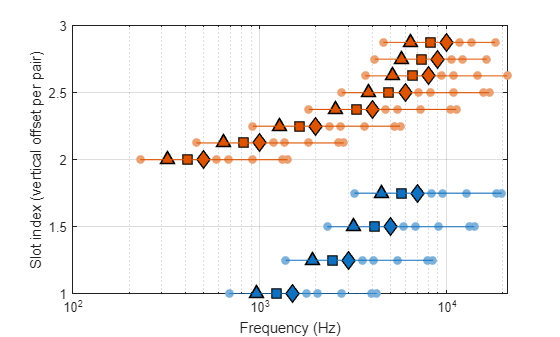

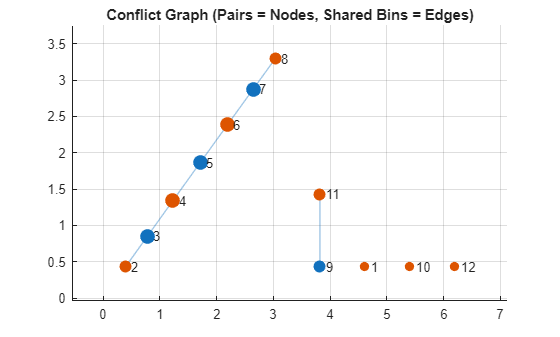


% ---------- Simple visualization (highlight main freqs f1,f2,DP=2f1-f2) ----------
figure('Name','Scheduled groups (frequencies)');
hold on;

% Slot colors
nSlots = max(1,numel(groups));
colors = lines(nSlots);

% Marker shapes for roles
markerMain = {'s','d','^'};         % markers for f1,f2,DP
roleNames = {'f1','f2','2f1-f2'};

% visual params
alphaFactor = 0.45;        % how faded the "other" frequencies are (0..1)
mainMarkerSize = 9;
otherMarkerSize = 6;
mainLineWidth = 1.2;

for s = 1:numel(groups)
    idxs = groups{s}(:);
    baseColor = colors(mod(s-1,size(colors,1))+1,:);
    fadedColor = (1-alphaFactor)*baseColor + alphaFactor*[1 1 1]; % fade toward white

    for k = 1:numel(idxs)
        i = idxs(k);
        fRow = freqsAll(i, :);
        valid = ~isnan(fRow);
        fRow = fRow(valid);
        y = s + (k-1)/max(1,numel(idxs));  % small vertical offset per pair

        % identify main frequencies for this pair
        f1 = pairs(i,1);
        f2 = pairs(i,2);
        dp = 2*f1 - f2;

        % Plot "other" frequencies (all valid except the three mains) as faded markers
        isMain = abs(fRow - f1) < 1e-9 | abs(fRow - f2) < 1e-9 | abs(fRow - dp) < 1e-9;
        others = fRow(~isMain);
        if ~isempty(others)
            plot(others, y*ones(size(others)), 'o', ...
                'Color', fadedColor, 'MarkerFaceColor', fadedColor, 'MarkerSize', otherMarkerSize);
        end

        % Plot main frequencies with distinct shapes but colored by slot
        plot(f1, y, markerMain{1}, 'MarkerSize', mainMarkerSize, ...
            'MarkerEdgeColor','k', 'MarkerFaceColor', baseColor, 'LineWidth', mainLineWidth);
        plot(f2, y, markerMain{2}, 'MarkerSize', mainMarkerSize, ...
            'MarkerEdgeColor','k', 'MarkerFaceColor', baseColor, 'LineWidth', mainLineWidth);
        plot(dp, y,  markerMain{3}, 'MarkerSize', mainMarkerSize, ...
            'MarkerEdgeColor','k', 'MarkerFaceColor', baseColor, 'LineWidth', mainLineWidth);

        % Connect all frequencies for this pair with a thin line in slot color
        if numel(fRow) > 1
            fRowSorted = sort(fRow);
            plot(fRowSorted, y*ones(size(fRowSorted)), '-', 'Color', baseColor, 'LineWidth', 0.8);
        end
    end
end

set(gca,'xscale','log');
xlabel('Frequency (Hz)');
ylabel('Slot index (vertical offset per pair)');
grid on; box on;

% Legend:
% - slot color patches
% - role markers
legendHandles = gobjects(0);
legendLabels = {};

% slot color entries (show up to first 10 slots to avoid huge legends)
maxLegendSlots = min(nSlots, 10);
for s = 1:maxLegendSlots
    h = plot(nan, nan, 's', 'MarkerFaceColor', colors(s,:), 'MarkerEdgeColor', 'k', 'MarkerSize', 8);
    legendHandles(end+1) = h; %#ok<SAGROW>
    legendLabels{end+1} = sprintf('Slot %d', s); %#ok<SAGROW>
end

% role markers
for r = 1:numel(markerMain)
    h = plot(nan, nan, markerMain{r}, 'MarkerSize', mainMarkerSize, ...
        'MarkerEdgeColor','k', 'MarkerFaceColor', [0 0 0]); % black face for role legend
    legendHandles(end+1) = h; %#ok<SAGROW>
    legendLabels{end+1} = roleNames{r}; %#ok<SAGROW>
end


%-----------------
%----------------
%-----------------
% ---------- Build conflict graph from usesBin
% ---------------------------------
% Nodes = pairs
% Edge between i and j if they share ANY bin

nPairs = size(usesBin,1);

% Initialize adjacency matrix
adjMat = false(nPairs);

for b = 1:size(usesBin,2)
    users = find(usesBin(:,b));
    if numel(users) > 1
        % Create all pairwise connections (clique)
        for k1 = 1:numel(users)
            for k2 = k1+1:numel(users)
                i = users(k1);
                j = users(k2);
                adjMat(i,j) = true;
                adjMat(j,i) = true;
            end
        end
    end
end

% Create graph object
G = graph(adjMat);

% ---------- Plot graph ----------
figure('Name','Conflict Graph');
hold on;

% Layout (force-directed gives good structure)
p = plot(G, 'Layout','force');

title('Conflict Graph (Pairs = Nodes, Shared Bins = Edges)');

% ---------- Color nodes by slot assignment ----------
if exist('groups','var')
    nSlots = numel(groups);
    colors = lines(nSlots);

    nodeColors = zeros(nPairs,3); % RGB per node

    for s = 1:nSlots
        idxs = groups{s};
        nodeColors(idxs,:) = repmat(colors(s,:), numel(idxs), 1);
    end

    p.NodeColor = nodeColors;
end

% ---------- Improve appearance ----------
p.MarkerSize = 6 + 2*degree(G);  % bigger nodes = more conflicts
p.LineWidth = 0.5;
p.EdgeAlpha = 0.4;

% Label nodes with pair index
p.NodeLabel = arrayfun(@num2str, 1:nPairs, 'UniformOutput', false);

% ---------- Optional: annotate with frequencies ----------
% Uncomment if you want f2 labels instead
% labels = arrayfun(@(i) sprintf('%.0f', pairs(i,2)), 1:nPairs, 'UniformOutput', false);
% p.NodeLabel = labels;

grid on;


